% load dataset
PATH = [pwd() '/'];
load([PATH, 'task_conditions'], 'conditions')
load([PATH, 'trial_averages'], 'psths')
load([PATH, 'single_trials'], 'forces', 'spikes')

astable = @(X) cell2table(X(2:end,:), 'VariableNames', X(1,:));
conditions = astable(conditions);
psths = astable(psths);
forces = astable(forces);
spikes = astable(spikes);

## Plot conditions

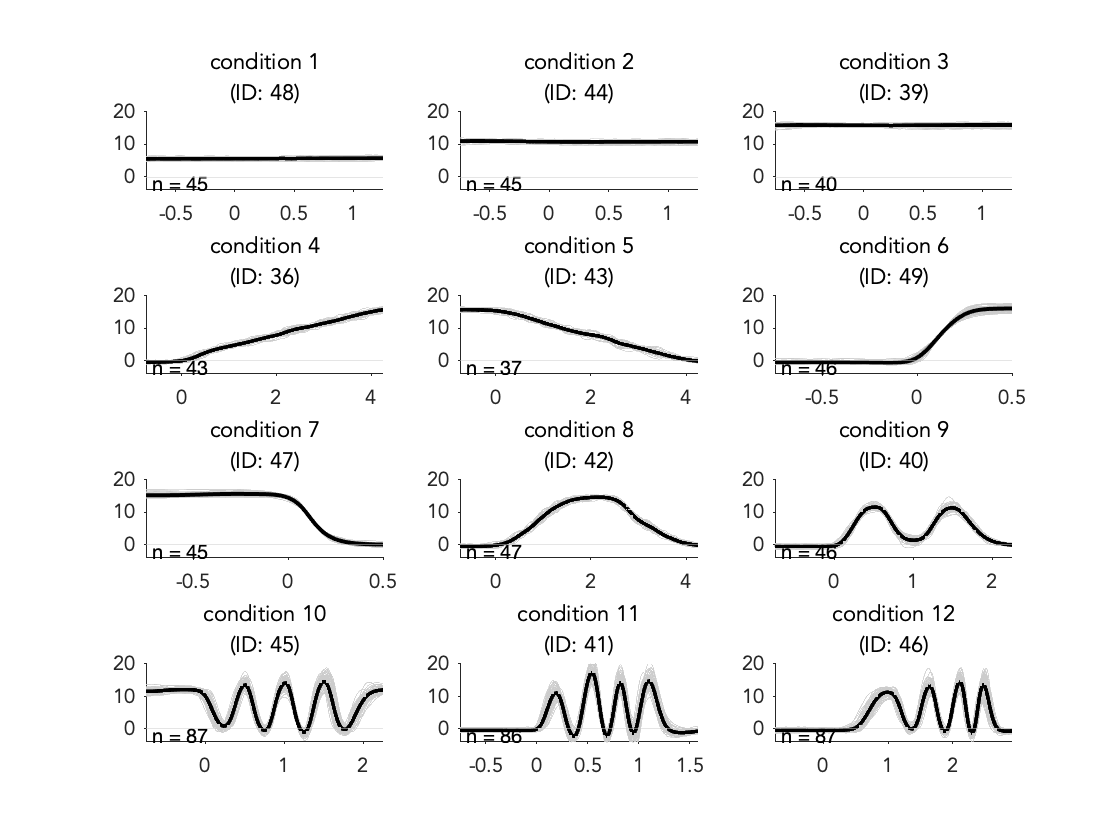

plotforce(forces, conditions, 'dynamic', 1)

## Get example keys for each experiment

experimentTypes = {'stim', 'dynamic', 'posture'};

keySet = cell2struct(cell(length(experimentTypes),1), experimentTypes);

for iExp = 1:length(experimentTypes)
    switch experimentTypes{iExp}
        case 'stim'
            condIndexes = [6, 7, 5];
            keys = cell(length(condIndexes), 1);
            for ii = 1:length(condIndexes)
                newKey = @(muId) struct(...
                    'experiment',experimentTypes{iExp},'session_index',1,...
                    'condition_index',condIndexes(ii),'motor_unit_id',muId);
                keys{ii} = getkeys(conditions, arrayfun(@(muId) newKey(muId), [206,215]), 'psths', psths);
            end
            
        case 'dynamic'
            condIndexes = [4, 11];
            keys = cell(length(condIndexes), 1);
            for ii = 1:length(condIndexes)
                newKey = @(muId) struct(...
                    'experiment',experimentTypes{iExp},'session_index',1,...
                    'condition_index',condIndexes(ii),'motor_unit_id',muId);
                keys{ii} = getkeys(conditions, arrayfun(@(muId) newKey(muId), [311, 309]), 'psths', psths);
            end
            
        case 'posture'
            condBlocks = [1, 2];
            keys = cell(length(condBlocks), 1);
            for ii = 1:length(condBlocks)
                newKey = @(muId) struct(...
                    'experiment',experimentTypes{iExp},'session_index',1,...
                    'condition_block',condBlocks(ii),'condition_index',5,'motor_unit_id',muId);
                keys{ii} = getkeys(conditions, arrayfun(@(muId) newKey(muId), [158, 159]), 'psths', psths);
            end
    end
    
    keySet.(experimentTypes{iExp}) = keys;
end

## Plot PSTHs over time

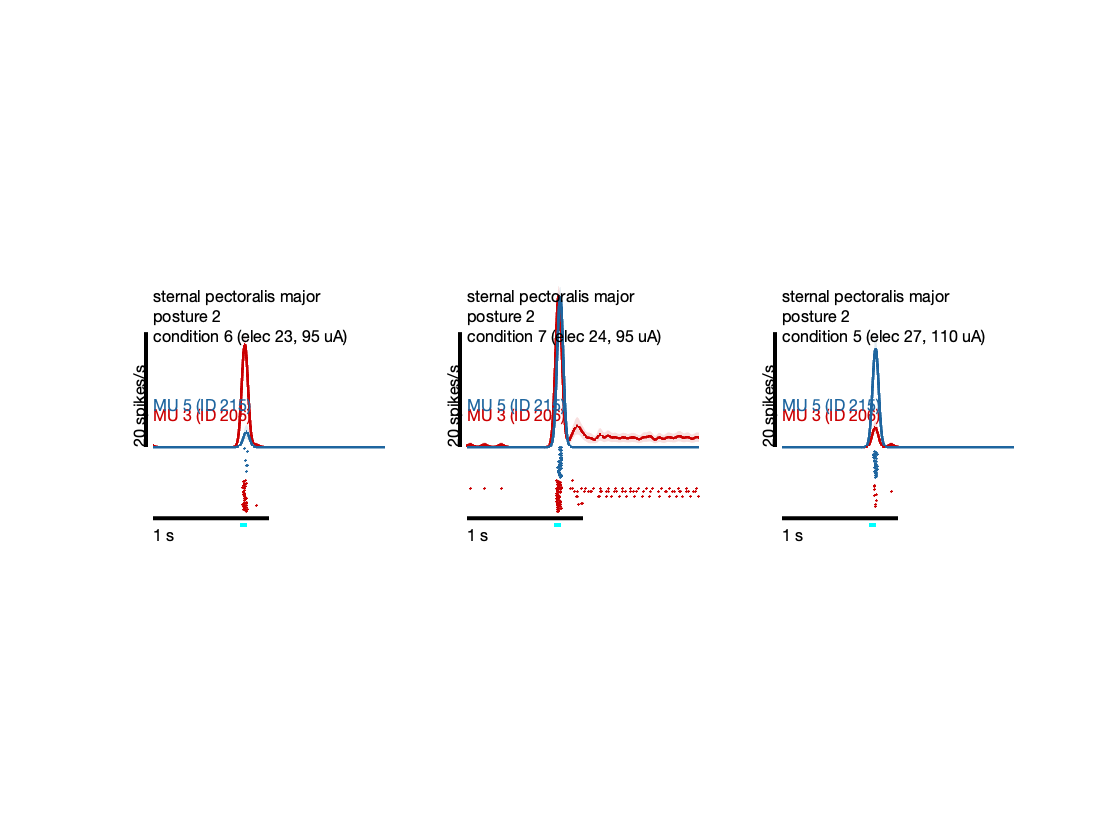

plotpsth(psths, conditions, keySet.('stim'), 'spikes', spikes, 'orient', 'horizontal')

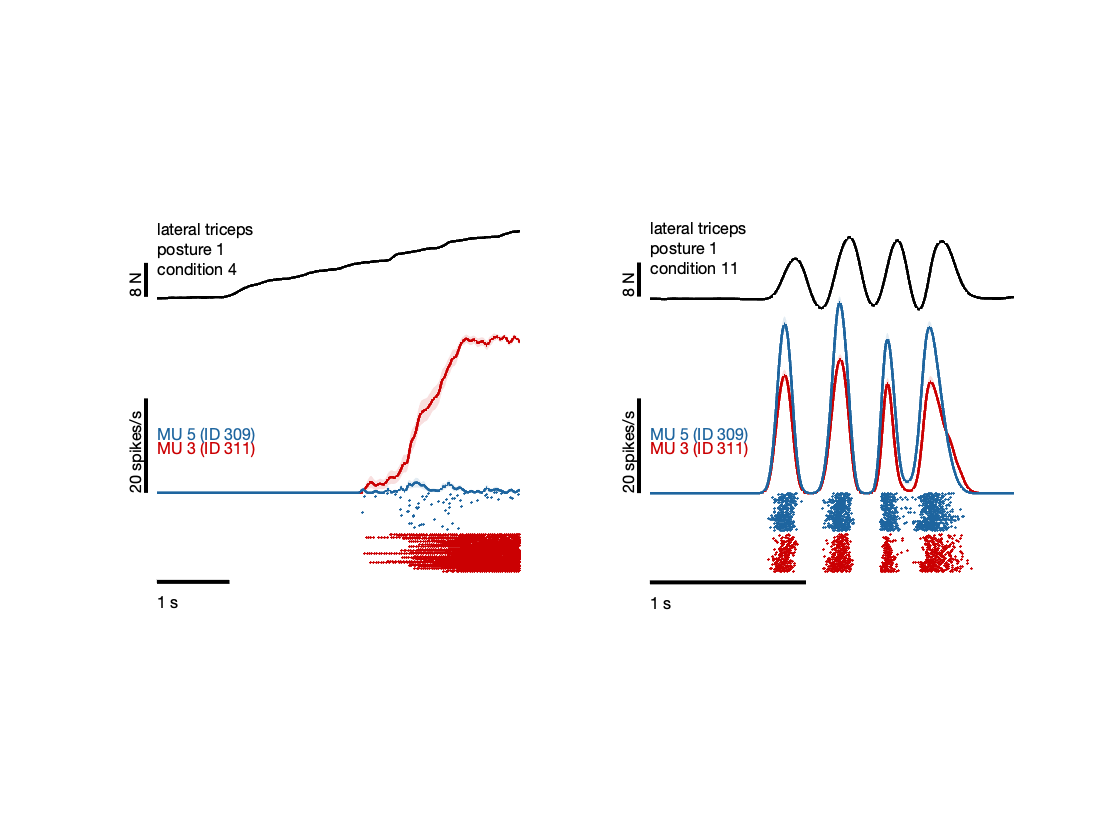

plotpsth(psths, conditions, keySet.('dynamic'), 'forces', forces, 'spikes', spikes)

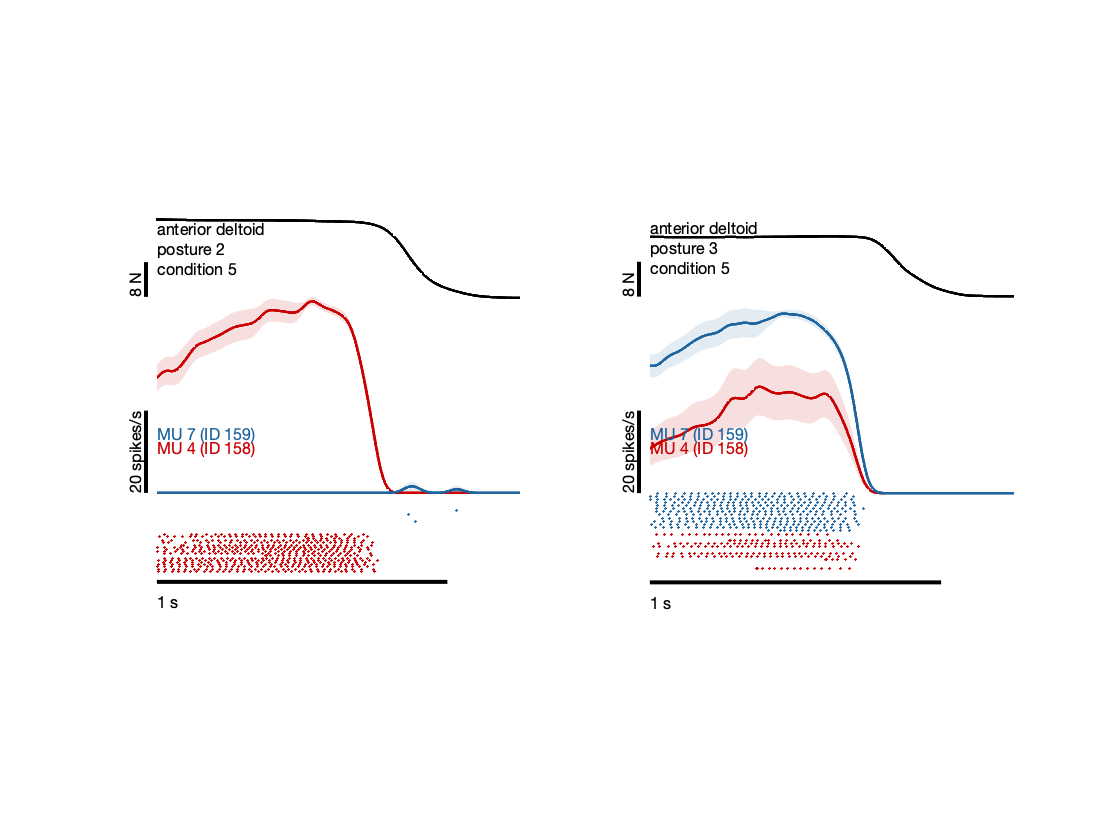

plotpsth(psths, conditions, keySet.('posture'), 'forces', forces, 'spikes', spikes)

## Plot PSTHs in state space

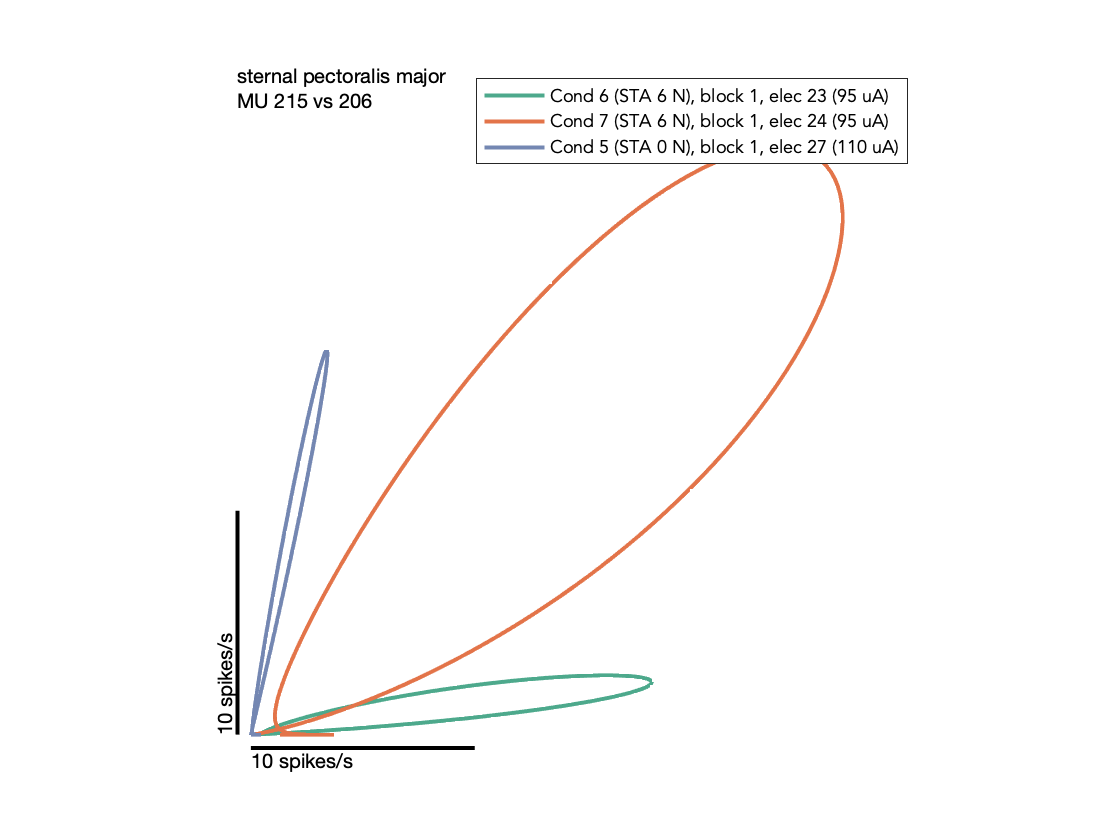

plotpsthstate(psths, conditions, {keySet.('stim')})

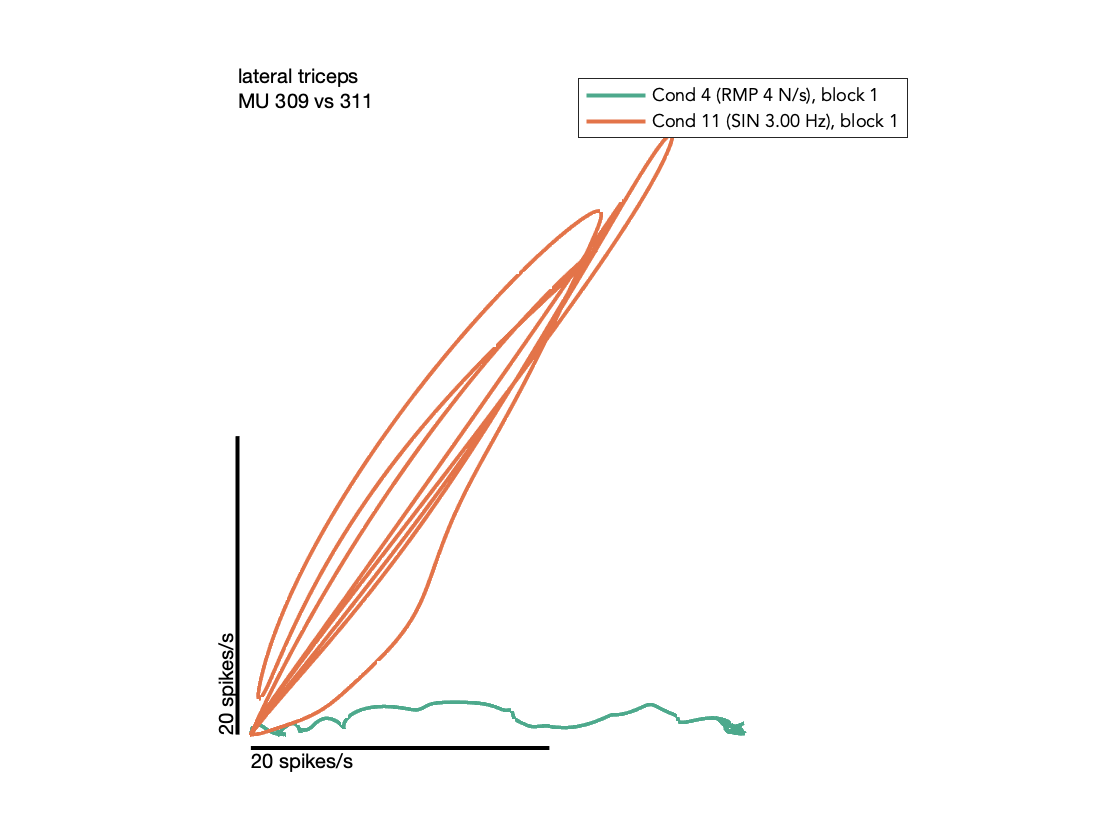

plotpsthstate(psths, conditions, {keySet.('dynamic')})

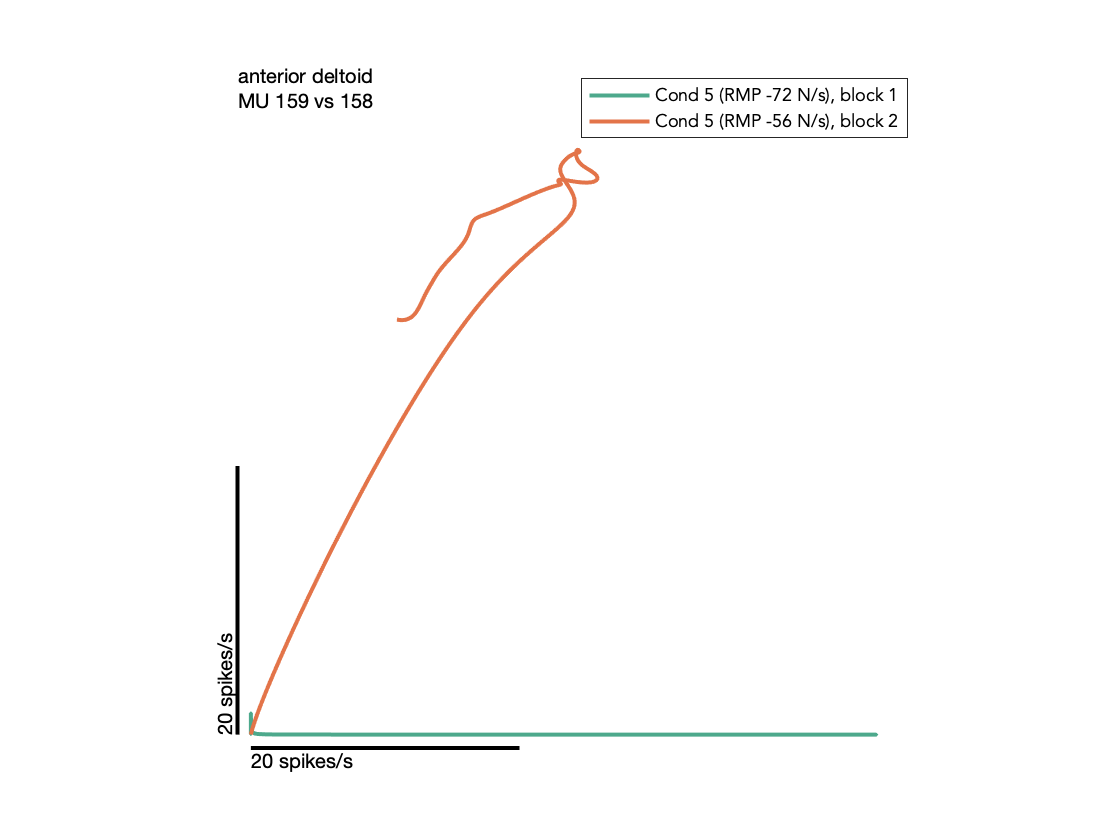

plotpsthstate(psths, conditions, {keySet.('posture')})

## Compute MU displacement and MNP dispersion

% replicate Fig. 3b for 2 stim sessions

% sampling rate
Fs = 1000;

% session x condition set (1-stim vs. all-stim)
[dMU, dMNP] = deal(cell2struct(cell(length(experimentTypes),1), experimentTypes));

for iExp = 1:length(experimentTypes)
    experiment = experimentTypes{iExp};
    switch experiment
        case 'stim'
            dMU.(experiment) = zeros(2,2);
            dMNP.(experiment) = zeros(2,2);
            
            for iSess = 1:2
                T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess,'target_offset',0));
                T = T(T.stim_id > 0,:);
                keys = getkeys(conditions, table2struct(T(:,1:4)));
                
                psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                
                % each condition separately ("1-stim")
                displacements = cellfun(@(R) mudisplacement({R}, Fs), psth, 'uni', false);
                dMU.(experiment)(iSess,1) = max(cellfun(@max, displacements));
                
                dispersions = cellfun(@(R) mnpdispersion({R}, Fs), psth, 'uni', false);
                dMNP.(experiment)(iSess,1) = max(cellfun(@max, dispersions));
                
                % all conditions ("all-stim")
                dMU.(experiment)(iSess,2) = max(mudisplacement(psth, Fs));
                dMNP.(experiment)(iSess,2) = max(mnpdispersion(psth, Fs));
            end
            
        case 'dynamic'
            dMU.(experiment) = zeros(2,2);
            dMNP.(experiment) = zeros(2,2);
            
            for iSess = 1:2
                
                % slow ramp up
                T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess,...
                    'target_type','RMP','target_amplitude',1,'target_duration',4));
                keys = getkeys(conditions, table2struct(T(:,1:4)));
                
                psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                
                dMU.(experiment)(iSess,1) = max(mudisplacement(psth, Fs));
                dMNP.(experiment)(iSess,1) = max(mnpdispersion(psth, Fs));
                
                % all conditions
                T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess));
                keys = getkeys(conditions, table2struct(T(:,1:4)));
                
                psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                
                dMU.(experiment)(iSess,2) = max(mudisplacement(psth, Fs));
                dMNP.(experiment)(iSess,2) = max(mnpdispersion(psth, Fs));
            end
            
        case 'posture'
            dMU.(experiment) = zeros(2,3);
            dMNP.(experiment) = zeros(2,3);
            
            for iSess = 1:2
                
                % slow ramp up (within postures)
                T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess,...
                    'target_type','RMP','target_duration',4));
                keys = getkeys(conditions, table2struct(T(:,1:4)));
                
                psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                
                displacements = cellfun(@(R) mudisplacement({R}, Fs), psth, 'uni', false);
                dMU.(experiment)(iSess,1) = max(cellfun(@max, displacements));
                
                dispersions = cellfun(@(R) mnpdispersion({R}, Fs), psth, 'uni', false);
                dMNP.(experiment)(iSess,1) = max(cellfun(@max, dispersions));
                
                % all conditions (within postures)
                for iBlock = 1:2
                    T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess,...
                        'condition_block',iBlock));
                    keys = getkeys(conditions, table2struct(T(:,1:4)));
                    
                    psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                    psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                    
                    dMU.(experiment)(iSess,2) = max(dMU.(experiment)(iSess,2), max(mudisplacement(psth, Fs)));
                    dMNP.(experiment)(iSess,2) = max(dMNP.(experiment)(iSess,2), max(mnpdispersion(psth, Fs)));
                end
                
                % all conditions (across postures)
                T = selectrows(conditions, struct('experiment',experiment,'session_index',iSess));
                keys = getkeys(conditions, table2struct(T(:,1:4)));
                
                psth = arrayfun(@(key) selectrows(psths,key), keys, 'uni', false);
                psth = cellfun(@(T) cell2mat(T.motor_unit_psth), psth, 'uni', false);
                
                dMU.(experiment)(iSess,3) = max(mudisplacement(psth, Fs));
                dMNP.(experiment)(iSess,3) = max(mnpdispersion(psth, Fs));
            end
    end
end

## Plot displacement and dispersion

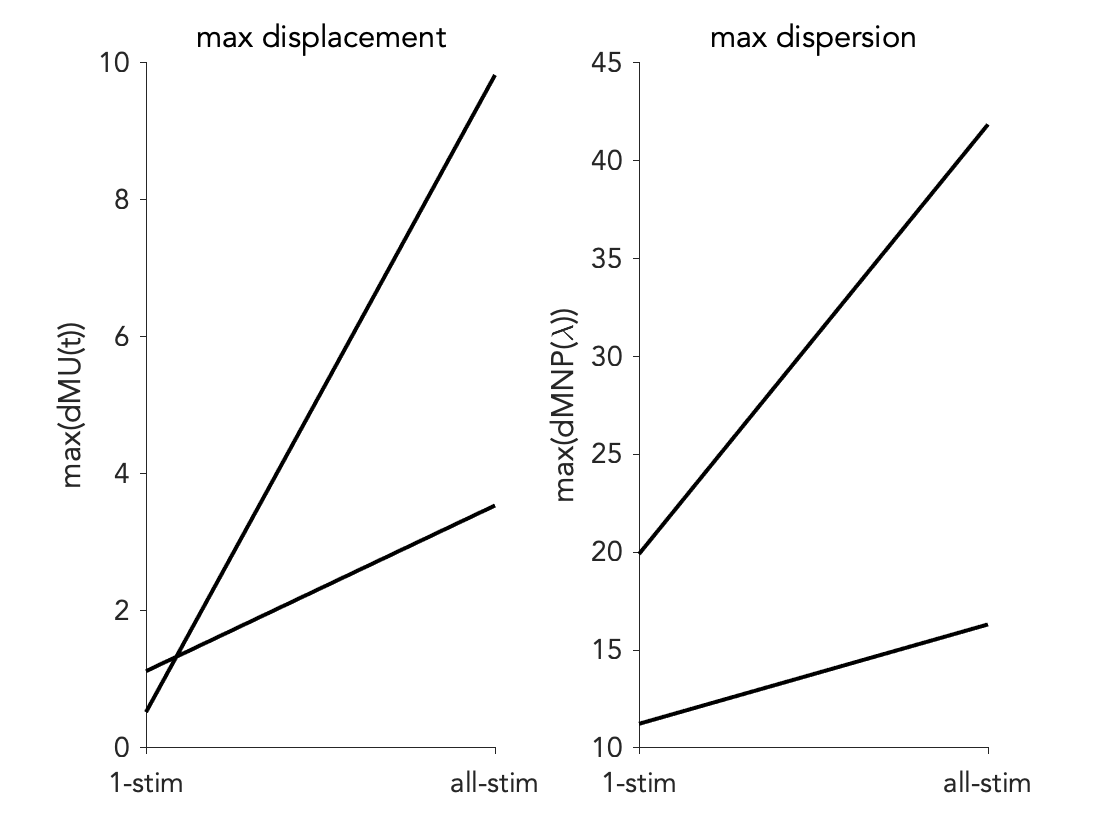

% stim
figure

subplot(121)
plot(dMU.stim', 'k', 'linewidth', 2)
box off
xticks([1,2])
set(gca, 'XTickLabel', {'1-stim','all-stim'}, 'FontSize', 14)
ylabel('max(dMU(t))')
title('max displacement')

subplot(122)
plot(dMNP.stim', 'k', 'linewidth', 2)
box off
xticks([1,2])
set(gca, 'XTickLabel', {'1-stim','all-stim'}, 'FontSize', 14)
ylabel('max(dMNP(\lambda))')
title('max dispersion')

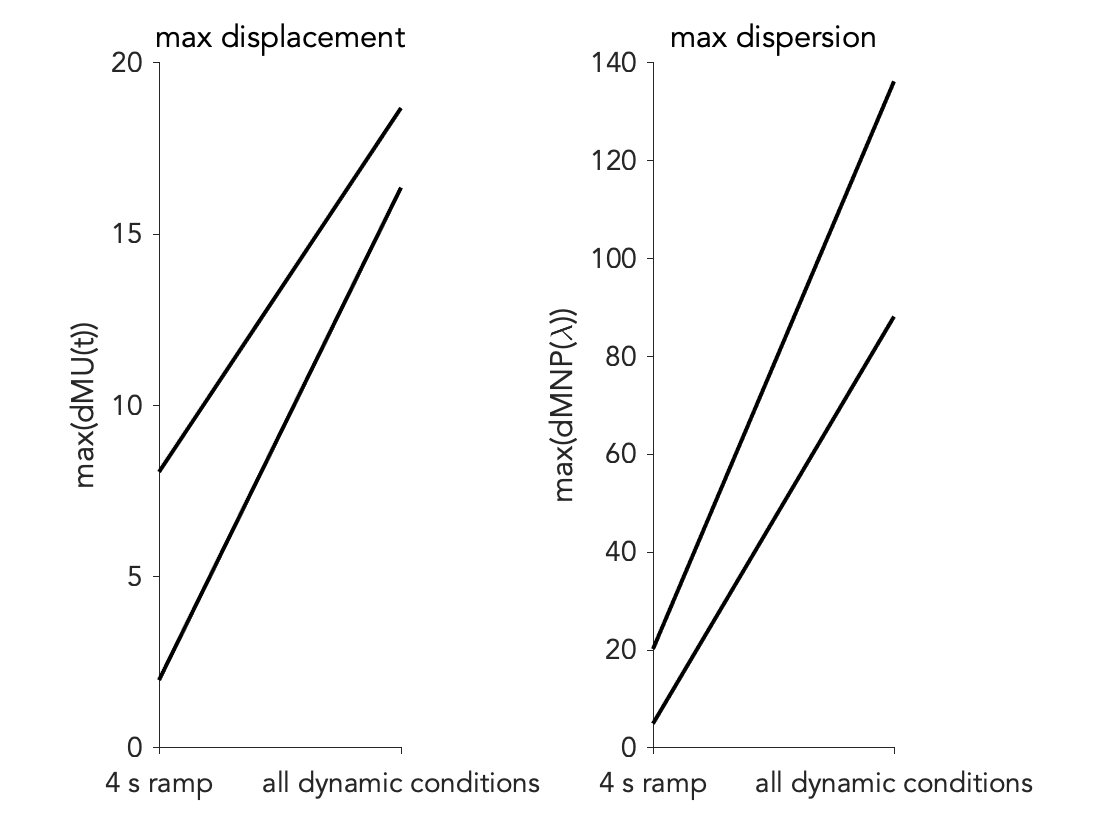

% dynamic
figure

subplot(121)
plot(dMU.dynamic', 'k', 'linewidth', 2)
box off
xticks([1,2])
set(gca, 'XTickLabel', {'4 s ramp','all dynamic conditions'}, 'FontSize', 14)
ylabel('max(dMU(t))')
title('max displacement')

subplot(122)
plot(dMNP.dynamic', 'k', 'linewidth', 2)
box off
xticks([1,2])
set(gca, 'XTickLabel', {'4 s ramp','all dynamic conditions'}, 'FontSize', 14)
ylabel('max(dMNP(\lambda))')
title('max dispersion')

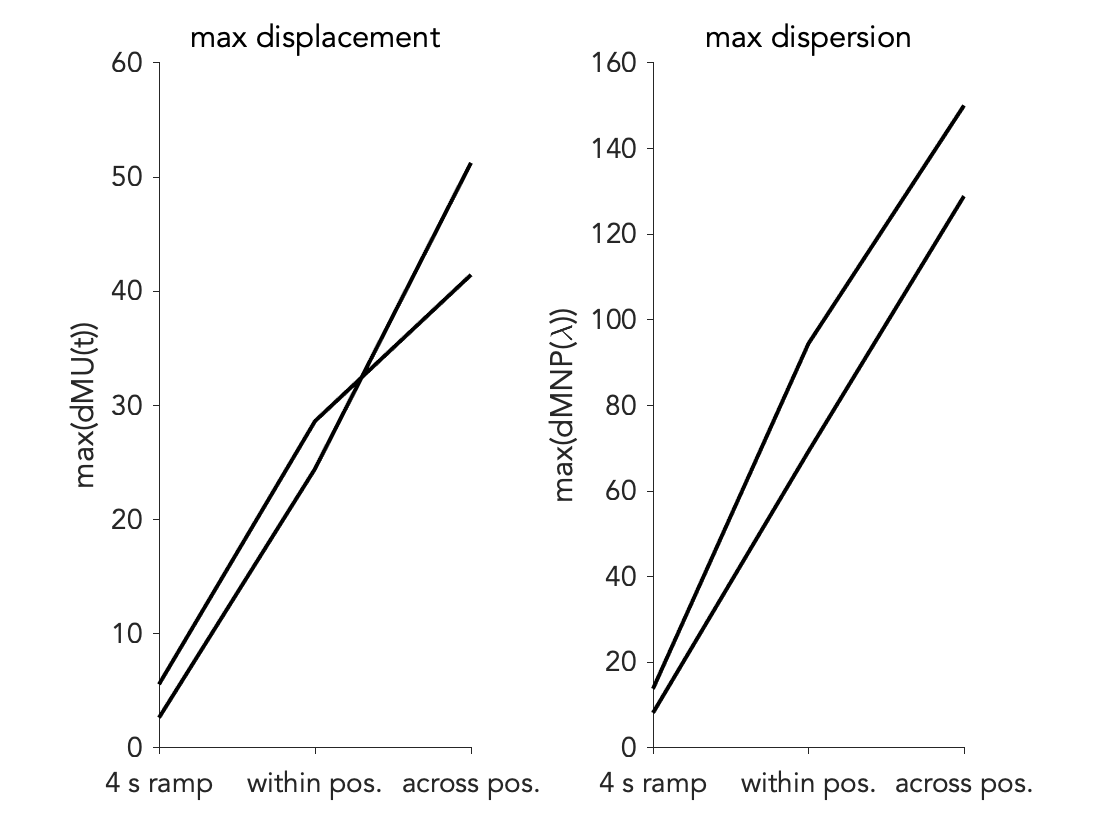

% posture
figure

subplot(121)
plot(dMU.posture', 'k', 'linewidth', 2)
box off
xticks(1:3)
set(gca, 'XTickLabel', {'4 s ramp','within pos.','across pos.'}, 'FontSize', 14)
ylabel('max(dMU(t))')
title('max displacement')

subplot(122)
plot(dMNP.posture', 'k', 'linewidth', 2)
box off
xticks(1:3)
set(gca, 'XTickLabel', {'4 s ramp','within pos.','across pos.'}, 'FontSize', 14)
ylabel('max(dMNP(\lambda))')
title('max dispersion')